## Multiplikative Modultion (Cosinus): Q-PSK Signal

% Alles löschen und aufräumen
close all; clear all; clc;
% Zusätzlich Pfad vom ersten Übungsblatt angeben -> Für plotfft
addpath('../../../60_Labor/01_Uebungsblatt_Musterloesung/');   
addpath('../../../60_Labor/02_Uebungsblatt_Musterloesung/');   

### Anlegen der Signale

% Festlegung der Parameter
fa = 50e3; Ta = 1 / fa;
fs = 1000; Ts = 1 / fs;
fc = 8000;

% Erstellen von zufälligen Bits
Nbits = 50;
bits = round(rand(1, Nbits), 0);

% Berechnung der Signallänge für reeller harmonische Schwingung
Nsym = Nbits;
N_samples = floor(Nsym * (Ts / Ta)); 
Tq = Ta * (N_samples / 2) - Ta;

% Erzeugung der Signale
yqpsk = PskGen(bits, fs, fa, 'QPSK');
ycos_q = SigGen(Tq, fa, 'cos', fc);

### Darstellung des Basisband-Signals

disp('Q-PSK Signal im Basisband');

Q-PSK Signal im Basisband


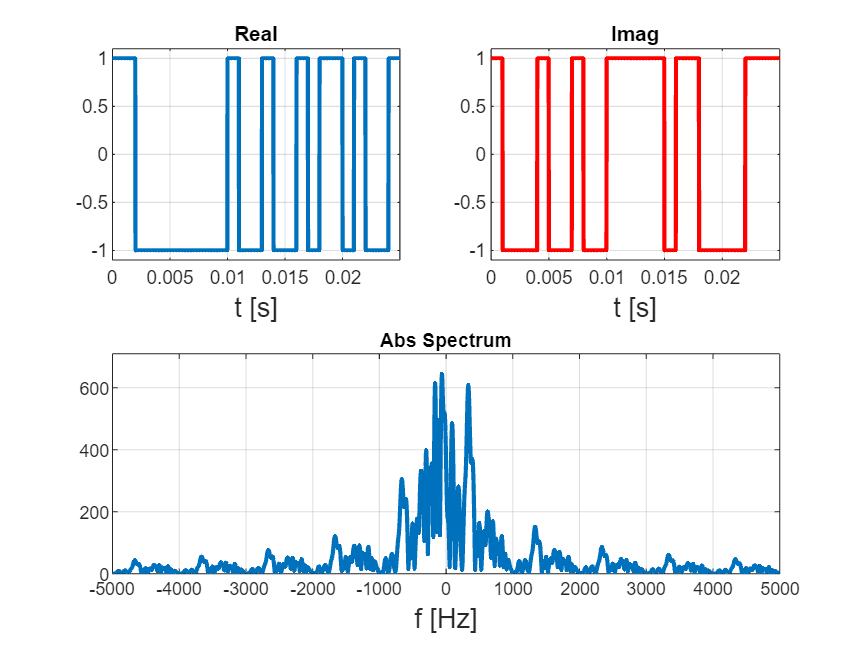

plotfft(yqpsk, fa, 'DisplaySignal', 'both', 'Nfft', 10240, 's', 1, 'Title', "Q-PSK-Signal im Basisband");
xlim([-5000, 5000]);

### Modulation des Signals

% Multiplikation der Signale
yqpsk_bp = yqpsk .* ycos_q;

### Darstellung des Bandpass-Signals

disp('Q-PSK Signal im Bandpass');

Q-PSK Signal im Bandpass


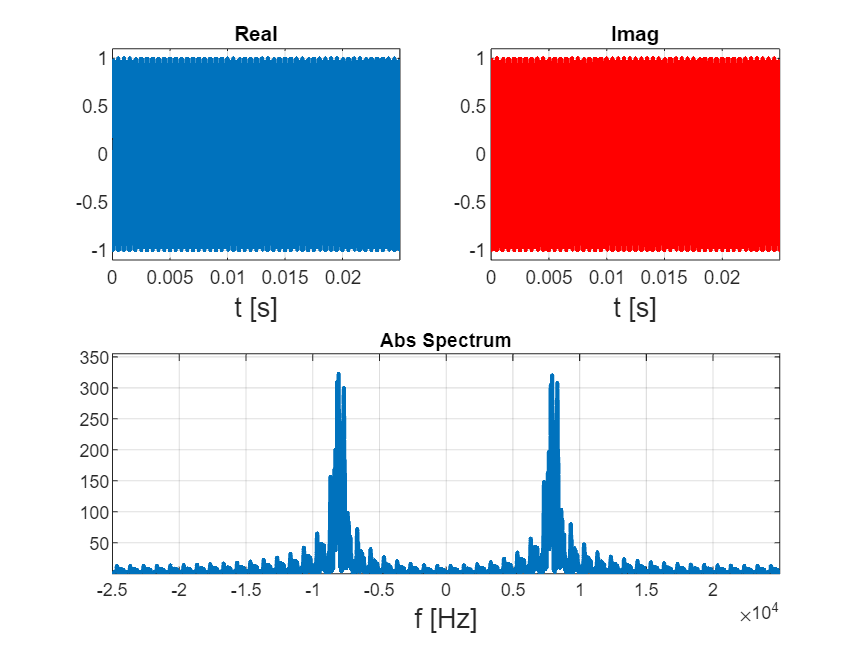

plotfft(yqpsk_bp, fa, 'DisplaySignal', 'both', 'Nfft', 10240, 's', 1, 'Title', "Q-PSK-Signal im Bandpass");

### Demodulation des Signals

% Multiplikation der Signale
yqpsk_bb = yqpsk_bp .* ycos_q;

### Darstellung des Demoduliertes Basisband-Signals

disp('Q-PSK Signal im Basisband (Nach Demodulation)');

Q-PSK Signal im Basisband (Nach Demodulation)


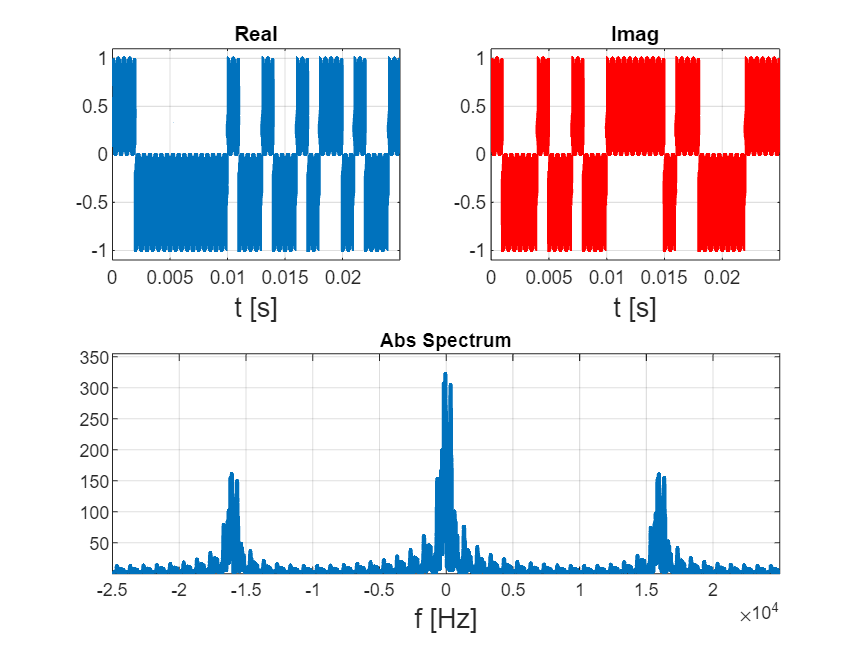

plotfft(yqpsk_bb, fa, 'DisplaySignal', 'both', 'Nfft', 10240, 's', 1, 'Title', "Q-PSK-Signal im Basisband (Nach Demodulation)");

### Anwendung des Tiefpasses

% Fir Filter Erstellen
firFilterObj = genFirFilter();
fir_coef = firFilterObj.Numerator;
fir_coef = fir_coef / sum(fir_coef);

% Fir Filter Anwenden
yqpsk_bb_fir = conv(yqpsk_bb, fir_coef);

% Ein- und Auschwingvorgänge entfernen
N_fir_half = floor (length(fir_coef) / 2);
yqpsk_bb_fir = yqpsk_bb_fir( N_fir_half : length(yqpsk_bb_fir) - N_fir_half);

### Darstellung des Demodulierten Tiefpass-Gefilterten Basisband-Signals

disp('Q-PSK Signal im Bandpass (Nach Demodulation und nach Tiefpass)');

Q-PSK Signal im Bandpass (Nach Demodulation und nach Tiefpass)


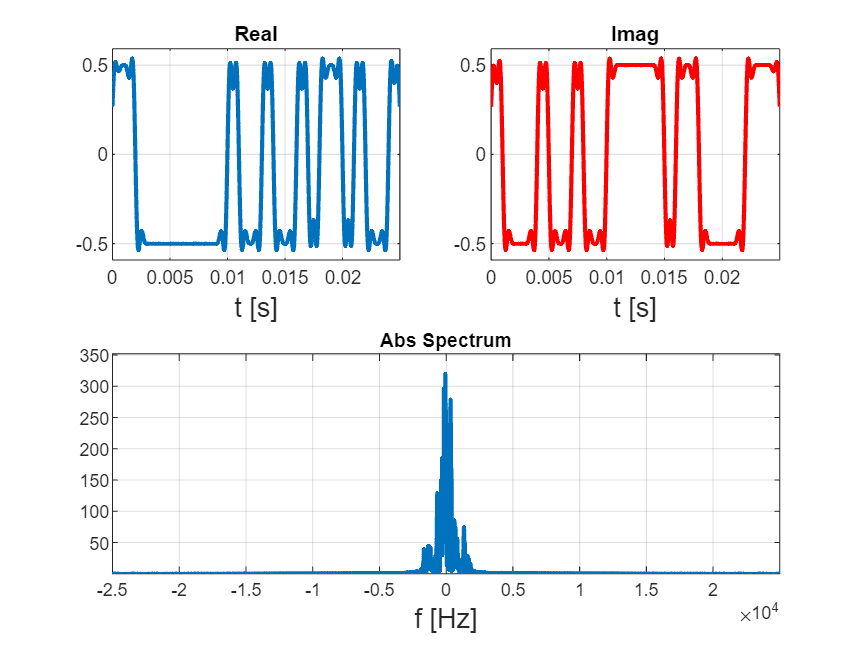

plotfft(yqpsk_bb_fir, fa, 'DisplaySignal', 'both', 'Nfft', 10240, 's', 1, 'Title', "Q-PSK-Signal im Basisband (Nach Demodulation und nach Tiefpass)");